# **Hierarchical Clustering Demo**

**Objective:**

Identify and group mechanical faults in a system using purely unsupervised machine learning techniques (Hierarchical Clustering and PCA).

**The Problem:**

 In predictive maintenance, we rarely have perfectly labeled data for every possible failure mode. We need to see if statistical features extracted from sensor data naturally group together to form distinct fault signatures.

**The Physical System:**

The system under study is a triplex reciprocating pump, a common industrial machine used for high-pressure fluid transport. It operates using three plungers driven by a single crankshaft, with each plunger's stroke phase-shifted by exactly 120 degrees. This overlapping mechanical action produces a continuous output flow characterized by a distinct, symmetrical "ripple." To generate our dataset without destroying a physical machine, we utilized a high-fidelity physical model to simulate hundreds of operational cycles.

**Data Generation:**

We recorded the output flow under both healthy conditions and various fault states, specifically introducing cylinder leaks and blocked inlets. Rather than simply toggling these faults "on" or "off," we swept the intensity of each defect, ranging from minor degradation to severe failure, and injected random sensor noise across the runs to accurately reflect messy, real-world industrial conditions.

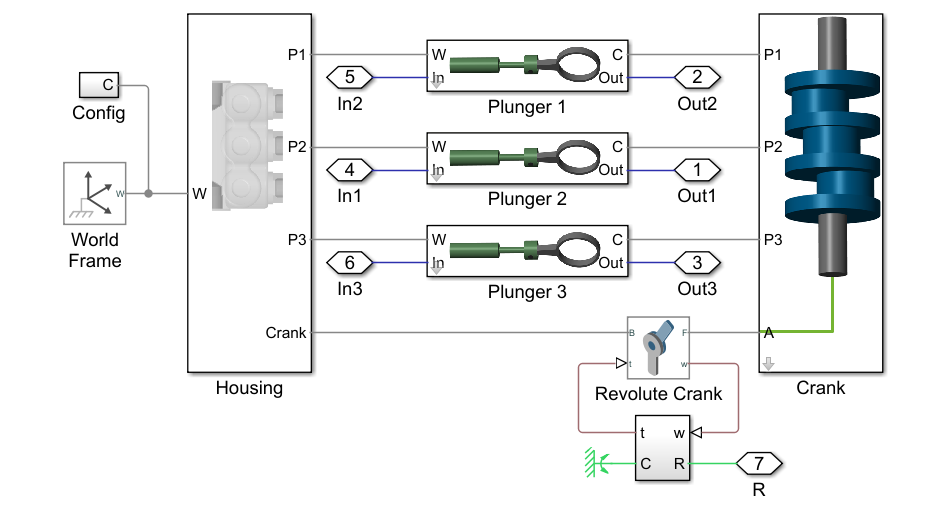

**Sensor:** 

Flow rate (m^3/s) measured at the pump outlet.

**Failure Modes:**

- Cylinder Leaks

- Blocked Inlets

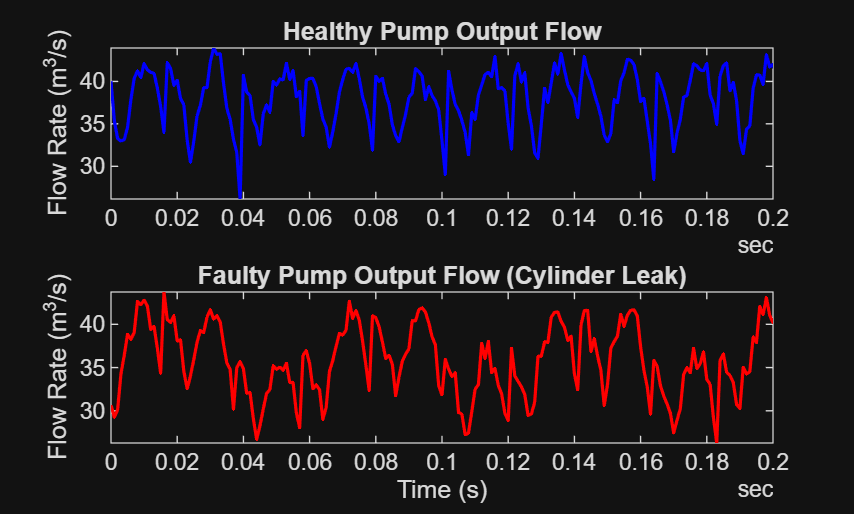

% Load the raw time-series data for a healthy vs. leaking pump
load('demo_signals.mat', 'healthy_flow', 'faulty_flow');

figure('Name', 'Raw Pump Flow Signatures');
subplot(2,1,1);
plot(healthy_flow.Time, healthy_flow.Data, 'b', 'LineWidth', 1.2);
title('Healthy Pump Output Flow'); ylabel('Flow Rate (m^3/s)');
xlim([seconds(0) seconds(0.2)]);

subplot(2,1,2);
plot(faulty_flow.Time, faulty_flow.Data, 'r', 'LineWidth', 1.2);
title('Faulty Pump Output Flow (Cylinder Leak)'); ylabel('Flow Rate (m^3/s)'); xlabel('Time (s)');
xlim([seconds(0) seconds(0.2)]);

processed the flow signals into 14 statistical features

**Frequency Domain Features**:

- Peak frequency

- Low-frequency power : total energy in 10-20 Hz range

- Mid-frequency power : total energy in 40-60 Hz

- High-frequency power : total energy above 100 Hz

- Spectral Kurtosis Peak : frequency band where largest impulse occurs

**Time Domain Features:**

- Mean

- Variance

- Skeness

- Kurtosis

- Peak to peak : absolute difference between max flow and min flow

- Crest Factor : dividing peak flow by RMS flow

- Root mean square : "effective energy"

- Mean absolute deviation

- Cumulative sume range

% Load the pre-processed 14-dimensional feature set
df = readtable('pump_features.csv');

% Isolate predictors (X) and true labels (for evaluation only)
X = df{:, 1:14};
true_labels = df.CombinedFlag;


**Why scale?** Distance-based algorithms (like Euclidean clustering or PCA) are highly sensitive to magnitude. 

**Equation:** Z = X-mu / sigma

% Standardize the feature matrix to have mean=0 and variance=1
X_scaled = zscore(X);


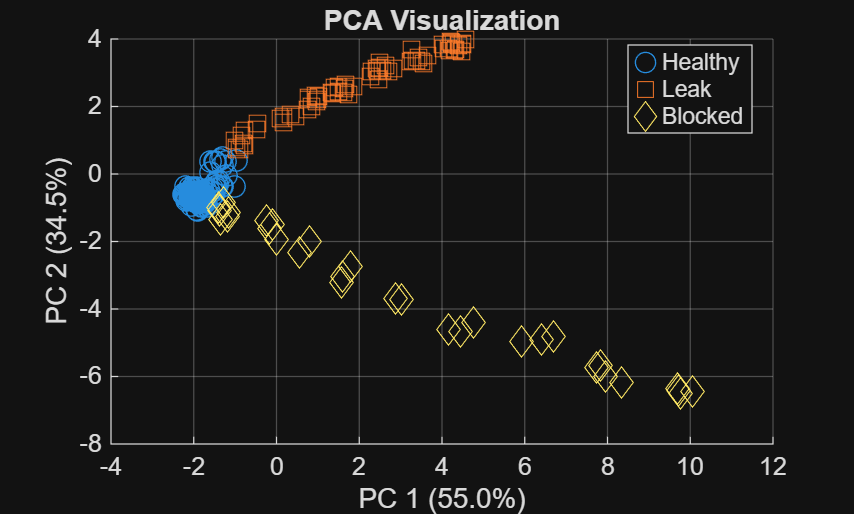

[~, score, ~, ~, explained] = pca(X_scaled);

classNames = {'Healthy', 'Leak', 'Blocked', 'Leak & Blocked', ...
              'Bearing', 'Bearing & Leak', 'Bearing & Blocked', 'All Faults'};
stringLabels = categorical(true_labels, 0:7, classNames);

figure('Name', 'PCA Cluster Visualization');
gscatter(score(:,1), score(:,2), stringLabels, lines(8), 'osd^v<>p', 8);
title('PCA Visualization');
xlabel(sprintf('PC 1 (%.1f%%)', explained(1))); ylabel(sprintf('PC 2 (%.1f%%)', explained(2)));
grid on;

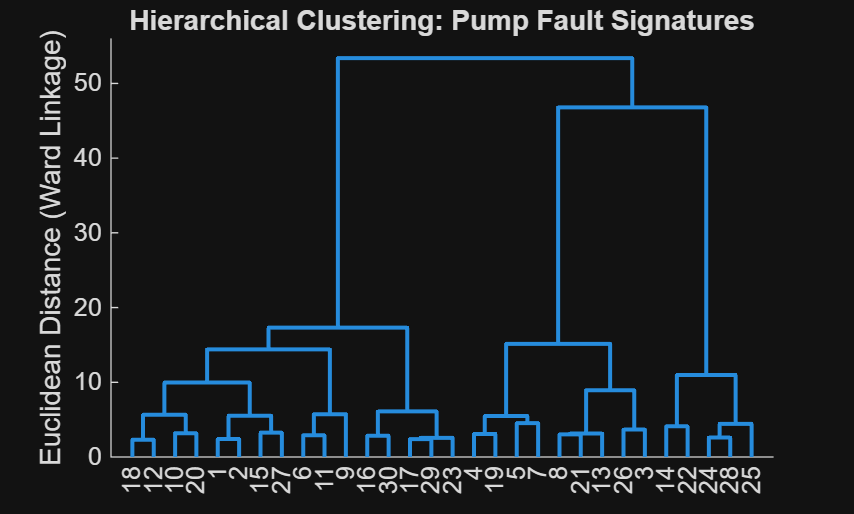

% Compute Euclidean distance and Ward linkage
distances = pdist(X_scaled, 'euclidean');
Z = linkage(distances, 'ward');

figure('Name', 'Fault Clustering Dendrogram');
[H, T, outperm] = dendrogram(Z, 30); % Truncated to 30 nodes for visibility
set(H, 'LineWidth', 1.5);
title('Hierarchical Clustering: Pump Fault Signatures');
ylabel('Euclidean Distance (Ward Linkage)');

**Takeaway:** Unsupervised learning shows us the underlying structure. We can clearly separate healthy pumps from leaking ones